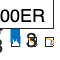

% This script calculates 10Be and 26Al concenrations in a bedrock profile at sea level
% and high latitude for various erosion rates (see 'erosion' variable) and using 
% threshold values in the LR04 benthis d18O stack to determine when ice
% cover is "on" or "off" (as shown in Fig. 3):

% acronyms used in code notes:
% G = glacial
% IG = interglacial
% NHG = northern hemisphere glaciation
% ka = thousand years before present

% INITIAL INPUTS %%%%%%%%%% ADJUST BEFORE RUNNING %%%%%%%%%%%
start = 8e6; % % start of model, years
stop = 0; % end of model, years
nhg = 3.0e6; % onset of northern hemisphere glaciation, years
benthic = xlsread('inputs.xlsx','LR04'); %import LR04 benthic stack 
time = flip((stop:1000:start)'); % yrs @ 1000 year timesteps
timestep = time(1)-time(2); % length of timestep
erosion = [1 10 100]; % ice erosion during glacials, mm/timestep(kyr)
backgrounderosion = 20; % pre-glacial background erosion (rock), mm/timestep(kyr)

trialvalues = 3:0.01:5; % threshold values used for LR04 to generate ice/no ice 
% scenarios; values set every 0.1 ‰ spanning 3 to 5 ‰

% END OF INITIAL INPUTS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% generate ice cover exposure history/scenarios (1s & 0s) based on prescribed thresholds ('trialvalues'): 
for i = 1:length(benthic)
    for ii = 1:length(trialvalues)
        if benthic(i) >= trialvalues(ii)
            icecover(i,ii) = 1;
        else
            icecover(i,ii) = 0;
        end
    end
end

% add pre-NHG exposure period (2s)
icecover = [(2.*ones((start-nhg)/timestep,length(icecover(1,:)))); icecover];

% import bedrock profile
prodpro = xlsread('inputs.xlsx','production_profiles');
depthinitial = prodpro(1:end,1)*10; % interpolating PR increment from cm to mm
depth = (0:1:depthinitial(end))'; % depth in mm

% import production rate profiles for 26al and 10be
pr_be10 = prodpro(:,8);
pr_be10 = interp1(depthinitial,pr_be10,depth);
pr_al26 = prodpro(:,9);
pr_al26 = interp1(depthinitial,pr_al26,depth);

conc_be10_1 = zeros(length(depth),length(trialvalues),length(erosion)); % make vector for 10be concentrations
conc_al26_1 = zeros(length(depth),length(trialvalues),length(erosion)); % make vector for 26al concentrations

% generate bedrock profile for 10be and 26al
for ii = 1:length(trialvalues)
    for iii = 1:length(erosion)
        concbe = conc_be10_1(:,ii,iii);
        concal = conc_al26_1(:,ii,iii);
        for i = 1:length(time)
            surfbe10(i,ii,iii) = concbe(1,1);
            surfal26(i,ii,iii) = concal(1,1);
            if icecover(i,ii) == 1 % glacial, ice sheet ON, production OFF, erosion ON
                erodeddepth = erosion(1,iii);
                % 10be
                concbe = concbe.*exp(-timestep.*(log(2)/1.4e6)); % decay only, production
                irdbe10(i,ii,iii) = mean(concbe(1:erodeddepth));
                topbe10 = concbe(erodeddepth+1:end,1);
                bottombe10 = zeros(erodeddepth,1);
                concbe = [topbe10; bottombe10];
                % 26al
                concal = concal.*exp(-timestep.*(log(2)/0.7e6));
                irdal26(i,ii,iii) = mean(concal(1:erodeddepth));
                topal26 = concal(erodeddepth+1:end,1);
                bottomal26 = zeros(erodeddepth,1);
                concal = [topal26; bottomal26];
            elseif icecover(i,ii) == 2 % pre-glacial, no ice cover or IRD, only background erosion, exposure, and decay
                % 10be
                irdbe10(i,ii,iii) = 0;
                concbe = concbe.*exp(-timestep.*(log(2)/1.4e6)) + pr_be10.*timestep; % ice cover should all be 0 (no ice)
                topbe10 = concbe(backgrounderosion+1:end,1);
                bottombe10 = zeros(backgrounderosion,1);
                concbe = [topbe10; bottombe10];
                % 26al
                irdal26(i,ii,iii) = 0;
                backgrounderosion = 20;
                concal = concal.*exp(-timestep.*(log(2)/0.7e6)) + pr_al26.*timestep; % ice cover should all be 0 (no ice)
                topal26 = concal(backgrounderosion+1:end,1);
                bottomal26 = zeros(backgrounderosion,1);
                concal = [topal26; bottomal26];
            else % interglacial, ice sheet OFF, production & decay ON
                % 10be
                irdbe10(i,ii,iii) = 0;
                concbe = concbe.*exp(-timestep.*(log(2)/1.4e6)) + pr_be10.*timestep*(1-icecover(i,ii));
                % 26al
                irdal26(i,ii,iii) = 0;
                concal = concal.*exp(-timestep.*(log(2)/0.7e6)) + pr_al26.*timestep*(1-icecover(i,ii));
            end
        end
    end
end

% plotting threshold values vs. averaged LGP model results 

T1 = find(time==15000);
T2 = find(time==65000);

% find 10Be results from last glacial period (T2:T1) for each erosion rate
% (1 to 3)
LGP_10Be_1ER = surfbe10(T2:T1,:,1);
LGP_10Be_10ER = surfbe10(T2:T1,:,2);
LGP_10Be_100ER = surfbe10(T2:T1,:,3);

% find 26Al/10Be ratio results from last glacial period (T2:T1) for each erosion rate
% (1 to 3)
LGP_ratios_1ER = surfal26(T2:T1,:,1)./surfbe10(T2:T1,:,1);
LGP_ratios_10ER = surfal26(T2:T1,:,2)./surfbe10(T2:T1,:,2);
LGP_ratios_100ER = surfal26(T2:T1,:,3)./surfbe10(T2:T1,:,3);

% find the mean of 10Be concentrations across the last glacial period for
% each erosion rate
LGP_10Be_1ER = mean(LGP_10Be_1ER,1);
LGP_10Be_10ER = mean(LGP_10Be_10ER,1);
LGP_10Be_100ER = mean(LGP_10Be_100ER,1);

% find the mean of 26Al/10Be ratios across the last glacial period for each
% erosion rate
LGP_ratios_1ER = mean(LGP_ratios_1ER,1);
LGP_ratios_10ER = mean(LGP_ratios_10ER,1);
LGP_ratios_100ER = mean(LGP_ratios_100ER,1);

% plot results
figure 
subplot(1,3,1);
plot(time(5001:end),benthic)
hold on
xlabel('Time (years)')
ylabel('d18O (‰)')
xlim([0 3e6])
set(gca, 'YDir','reverse')
hold off

subplot(1,3,2);
semilogx(LGP_10Be_1ER,trialvalues)
hold on
semilogx(LGP_10Be_10ER,trialvalues)
semilogx(LGP_10Be_100ER,trialvalues)
ylim([2.5 5.5])
set(gca, 'YDir','reverse')
legend('1ER','10ER','100ER','Location','northoutside')

subplot(1,3,3);
plot(LGP_ratios_1ER,trialvalues)
hold on
plot(LGP_ratios_10ER,trialvalues)
plot(LGP_ratios_100ER,trialvalues)
ylim([2.5 5.5])
set(gca, 'YDir','reverse')
legend('1ER','10ER','100ER','Location','northoutside')